% Generate p1
p1 = [[0,0];[0,-1];[0,-2];[0,-3]];
d1 = [0 0.0; 0 -1].';
d2 = [-0.10 0 ; 0 1].';

ellipsetest = ellipse(1,2,0,0);

el =     0.5000         0
    0.4990    0.0634
    0.4960    0.1266
    0.4910    0.1893
    0.4840    0.2511
    0.4750    0.3120
    0.4642    0.3717
    0.4515    0.4298
    0.4369    0.4862
    0.4206    0.5406


% plot(ellipsetest(:,1),ellipsetest(:,2));

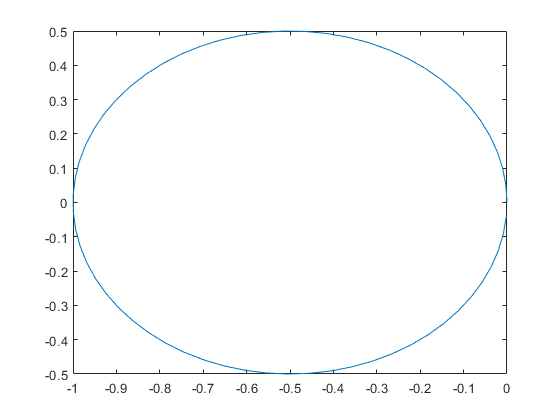

%Generate p2 using circle function at the bottom of the file
p2= -circle(-0.5,0,0.5);

midp2 = [p2(1:33,1) p2(1:33,2)];
% plot(midp2(:,1),midp2(:,2));
mid2p2 = [p2(31:63,1) p2(31:63,2)];

Q1 = midp2;
plot(Q1(:,1),Q1(:,2));
hold on
Q2 = Q1(size(Q1))-(d1);
plot(Q2(:,1),Q2(:,2))
hold on
cstQ2 = [Q2(size(Q2,1),1) Q2(size(Q2,1),2)];

Q3 = cstQ2-midp2;
plot(Q3(:,1),Q3(:,2))
hold on
cstQ3 = [Q3(size(Q3,1),1) Q3(size(Q3,1),2)]

cstQ3 =          0    0.9733


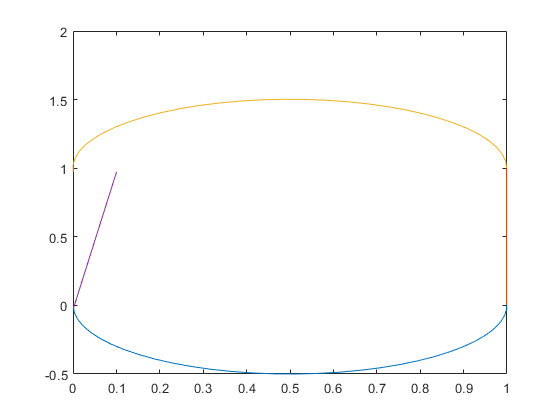

Q4 = cstQ3-(d2);
plot(Q4(:,1),Q4(:,2))
hold off

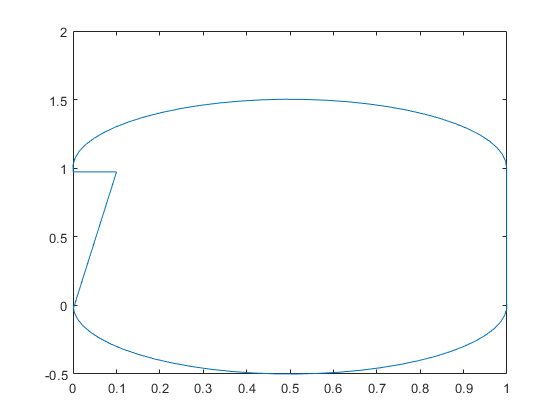



elipse = [Q1;Q2;Q3;Q4];
plot(elipse(:,1),elipse(:,2));


% p3 = -circle(-1,-1,1);
% p4 = [p2;p3];
% plot(p2(:,1),p2(:,2));
% hold on

%Generate p3 and p4. 

function p=circle(x,y,r)
p=[];
%create and plot a circle with radius r and origin (x,y)
    ang=0:0.1:2*pi; 
    xp=r*cos(ang);
    yp=r*sin(ang);
%     for i = 1:size(xp)
%         p= [p [x+xp;y+yp]'];
%     end
    plot(x+xp,y+yp);
    p=[x+xp;y+yp]';
end

function el = ellipse(a,b,x,y)
    ang = linspace(0,2*pi) ;
    x_coor = a/2*cos(ang) ;
    y_coor = b/2*sin(ang) ;
    el = [x_coor+x; y_coor+y].'
end


